# Entropic flux balance analysis

## **Author: Ronan Fleming, NUI Galway, Leiden University**

## INTRODUCTION

## PROCEDURE

Set the directory for results

basePath='~/work/sbgCloud';
resultsDirectory=[basePath '/programModelling/projects/thermoModel/results/entropicFBA'];

Set the model to load

if ~exist('model','var')
    modelToUse='iDN';
    %modelToUse='ecoli_core';
    %modelToUse = 'fork';
    modelToUse = 'single';
    %modelToUse='recon3';
     
    switch modelToUse
        case 'single'
            driver_singleModel
        case 'fork'
            driver_forkModel

        case 'ecoli_core'
            dataDirectory=[basePath '/data'];
            load([dataDirectory '/models/published/e_coli_core.mat']);
            if ~isfield(model,'SConsistentMetBool') || ~isfield(model,'SConsistentRxnBool')
                massBalanceCheck=0;
                [~, ~, ~, ~, ~, ~, model, ~] = findStoichConsistentSubset(model, massBalanceCheck, 0);
            end
            model.lb(ismember(model.rxns,'BIOMASS_Ecoli_core_w_GAM'))=0.1;
            
        case 'recon3'
%             genericModelName = 'Recon3DModel_301_thermoFeas_BBF.mat';
%             inputFolder = ['~' filesep 'work' filesep 'sbgCloud' filesep 'programReconstruction' filesep 'projects' filesep 'exoMetDN' filesep 'data' filesep 'xomics'];
%             load([inputFolder filesep genericModelName])
            
            genericModelName = 'Recon3DModel_301_xomics_input.mat';
            inputFolder = ['~' filesep 'work' filesep 'sbgCloud' filesep 'programExperimental' filesep 'projects' filesep 'xomics' filesep 'data' filesep 'Recon3D_301'];
            load([inputFolder filesep genericModelName])
            
            %load([dataDirectory '/models/unpublished/2016_07_13_Recon3_SConsistencyCheck.mat']);
            %model=modelRecon3model;

            
            %change onto uMol/gDW/hr
            model.lb = model.lb;
            model.ub = model.ub;
        case 'iDN'
            %load('~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/iDN1/iDopaNeuro1/iDopaNeuro1.mat')
            load('~/work/sbgCloud/programExperimental/projects/tracerBased/data/models/iDopaNeuro1.mat')
            model = iDopaNeuro1;
            clear Model
            clear modelGenerationReport
            
            %problematic reactions
%             {'34DHPHEt'}      {'3, 4-Dihydroxy-L-Phenylalanine Transport' }      -0.53635    0     {'34dhphe[e]  <=> 34dhphe[c] '}
%             {'URAt'    }      {'Uracil Transport via Faciliated Diffusion'}    -0.0013626    0     {'ura[e]  <=> ura[c] '        }
            model.lb(ismember(model.rxns,'34DHPHEt'))=-1e4;
            model.ub(ismember(model.rxns,'34DHPHEt'))= 1e4;
            model.lb(ismember(model.rxns,'URAt'))=-1e4;
            model.ub(ismember(model.rxns,'URAt'))= 1e4;
    end
end

Examine the constraints on the model

printConstraints(model,-1e4,1e4,model.SIntRxnBool)

    Reversible_Reaction     Name     lb     ub         equation      
    ___________________    ______    ___    __    ___________________

          {'AB'}           {'AB'}    -20    20    {'A[c]  <=> B[c] '}




printConstraints(model,-1e4,1e4,~model.SIntRxnBool)
printCouplingConstraints(model,1);

Set the data parameters for the entropic flux balance analysis problem

Linear optimisation direction

model.osenseStr = 'min';

Reaction parameters

model.cf=0.1;
model.cr=0.1;
model.g=2;
if 0
    quad = zeros(size(model.S,2),1);
    quad(~model.SIntRxnBool)=1;
    model.Q=diag(quad);
end

## Reaction parameters

Setting the bounds on reaction direction is important, because certain bounds may be incompatible with the existence of a thermodynamically feasible steady state

param.internalNetFluxBounds:     

'original' maintains direction and magnitude of net flux from model.lb & model.ub

'directional' maintains direction of net flux from model.lb & model.ub but not magnitude

'random' random net flux direction, replacing constraints from model.lb & model.ub

%param.internalNetFluxBounds='directional';
param.internalNetFluxBounds='original';
%param.internalNetFluxBounds='none';

Maximum permitted internal flux

param.maxUnidirectionalFlux=100;
%model.vfl = [0;0;0]

## Method parameters

param.method='fluxes';
param.method='fluxConc';
%param.method='fluxConcNorm';

## Metabolite parameters (only relevant if a concentration method chosen)

Standard chemical potential

model.u0=0.2;

Strictly positive weight on concentration entropy maximisation

model.f=1;

Scalar maximum permitted metabolite concentration

param.maxConc=1;

## Solver parameters

Set the solver

%param.solver='pdco';
param.solver='mosek';
if strcmp(param.solver,'mosek')
    %set default mosek parameters for this type of problem
    param=mosekParamSetEFBA(param);
end

Minimum permitted internal flux required for exponential cone reformulation

if strcmp(param.solver,'mosek')
    param.minUnidirectionalFlux=0;
end

Tolerances

param.feasTol=1e-7;

Printing level

param.printLevel=2; 
param.debug = 1;

Run entropic flux balance analysis

[solution,modelOut] = entropicFluxBalanceAnalysis(model,param);

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 9.2.37 (Build date: 2021-2-8 10:03:08)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : LO (linear optimization problem)
  Constraints            : 5               
  Cones                  : 0               
  Scalar variables       : 6               
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00        

model=modelOut;

Extract the fields of the solution structure

if solution.stat ~=1
    disp('No solution')
    return
end
[v,vf,vr,vt,y_N,z_v,z_dx,z_vf,z_vr,stat]=...
    deal(solution.v,solution.vf,solution.vr,solution.vt,solution.y_N,solution.z_v,solution.z_dx,solution.z_vf,solution.z_vr,solution.stat);
cf = model.cf;
cr = model.cr;

g=deal(model.g);
if isfield(solution,'x')
    [x, x0, z_x, z_x0, z_dx] = deal(solution.x, solution.x0, solution.z_x, solution.z_x0, solution.z_dx);
    [u0,f]=deal(model.u0,model.f);
    dx = x - x0;
end

 Extract the internal (N) and exchange (B) stoichiometric matrices  

N = model.S(:,model.SConsistentRxnBool);
B = model.S(:,~model.SConsistentRxnBool);

Extract the matrix of coupling constraints, if present

if isfield(model,'C')
    C = model.C(:,model.SConsistentRxnBool);
    y_C = solution.y_C;
end

Extract the objective on the internal reaction rates

e   = ones(length(vf),1);
ci = solution.osense*model.c(model.SConsistentRxnBool);

Compute the nullspace of the internal stoichiometric matrix

if 0
   %get nullspace of N
    [Z,rankS]=getNullSpace(N,0);
else
    Z=[];
end

if param.printLevel>2 || 1
    v_detailed=1;
else
    v_detailed=0;
end

Biochemical optimality conditions: steady state

if isfield(solution,'x')
    fprintf('%8.2g %s\n',norm(N*(vf - vr) - x + x0 - model.b,inf), '|| N*(vf - vr) - x + x0 - b ||_inf');
else
    fprintf('%8.2g %s\n',norm(model.S*v - model.b,inf), '|| S*v - b ||_inf');
end

       0 || N*(vf - vr) - x + x0 - b ||_inf


Optionally, display detailed properties of flux related solution vector

if v_detailed
    fprintf('%8.2g %s\n',sum(vf)+sum(vr),'sum(vf)+sum(vr) >= 0');
    fprintf('%8.2g %s\n',norm(g.*reallog(vf),inf),'|| g*log(vf) ||_inf');
    fprintf('%8.2g %s\n',norm(g.*reallog(vr),inf),'|| g*log(vr) ||_inf');
    fprintf('%8.2g %s\n',norm(cr,inf),'|| cr ||_inf');
    fprintf('%8.2g %s\n',norm(cf,inf),'|| cf ||_inf');
    fprintf('%8.2g %s\n',norm(ci,inf),'|| ci ||_inf');
    fprintf('%8.2g %s\n',norm(N'*y_N,inf),'|| N''*y_N ||_inf');
    fprintf('%8.2g %s\n',norm(z_v,inf),'|| z_v ||_inf');
    fprintf('%8.2g %s\n',norm(z_vf,inf),'|| z_vf ||_inf');
    fprintf('%8.2g %s\n',norm(z_vr,inf),'|| z_vr ||_inf');
    if isfield(model,'C')
        fprintf('%8.2g %s\n',norm(C'*y_C,inf),'|| C''*y_C ||_inf');
    end
end

     1.9 sum(vf)+sum(vr) >= 0


     0.1 || g*log(vf) ||_inf


     0.1 || g*log(vr) ||_inf


     0.1 || cr ||_inf


     0.1 || cf ||_inf


       0 || ci ||_inf


       0 || N'*y_N ||_inf


       0 || z_v ||_inf


 1.9e-13 || z_vf ||_inf


 1.9e-13 || z_vr ||_inf


if isfield(model,'C')
    fprintf('%8.2g %s\n',norm(g.*reallog(vf) + ci + cf + N'*y_N + C'*y_C + z_v + z_vf,inf), '|| g*log(vf) + ci + cf + N''*y_N + C''*y_C + z_v + z_vf ||_inf');
    fprintf('%8.2g %s\n',norm(g.*reallog(vr) - ci + cr - N'*y_N - C'*y_C - z_v + z_vr,inf),'|| g*log(vr) - ci + cr - N''*y_N - C''*y_C - z_v + z_vr ||_inf');
    fprintf('%8.2g %s\n',norm(   C'*y_C + z_v + z_vf,inf), '||  + C''*y_C + z_v + z_vf ||_inf');
    fprintf('%8.2g %s\n',norm( - C'*y_C - z_v + z_vr,inf),'||  - C''*y_C - z_v + z_vr ||_inf');
else
    fprintf('%8.2g %s\n',norm(g.*reallog(vf) + ci + cf + N'*y_N + z_v - z_vf,inf), '|| g*log(vf) + ci + cf + N''*y_N + z_v - z_vf ||_inf');
    fprintf('%8.2g %s\n',norm(g.*reallog(vr) - ci + cr - N'*y_N - z_v - z_vr,inf),'|| g*log(vr) - ci + cr - N''*y_N - z_v - z_vr ||_inf');
end

 1.6e-07 || g*log(vf) + ci + cf + N'*y_N + z_v - z_vf ||_inf


 1.6e-07 || g*log(vr) - ci + cr - N'*y_N - z_v - z_vr ||_inf


Derived biochemical optimality conditions (fluxes)

if isfield(model,'C')
    res = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*C'*y_C - 2*z_v - z_vr + z_vf;
    fprintf('%8.2g %s\n',norm(res,inf),'|| g*log(vr/vf) + cr - cf - 2*ci - 2*N''*y_N - 2*C''*y_C - 2*z_v - z_vr + z_vf ||_inf');
else
    res = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*z_v - z_vr + z_vf;
    fprintf('%8.2g %s\n',norm(res,inf),'|| g*log(vr/vf) + cr - cf - 2*ci - 2*N''*y_N - 2*z_v - z_vr + z_vf ||_inf');
end

       0 || g*log(vr/vf) + cr - cf - 2*ci - 2*N'*y_N - 2*z_v - z_vr + z_vf ||_inf


Optionally, display detailed properties of concentration related solution vector

if isfield(solution,'x')
    fprintf('\n%s\n','Optimality conditions (concentrations)')
    if v_detailed
        fprintf('%8.2g %s\n',norm(reallog(x),inf), '|| log(x)||_inf');
        fprintf('%8.2g %s\n',norm(u0,inf), '|| u0 ||_inf');
        fprintf('%8.2g %s\n',norm(y_N,inf), '|| y_N ||_inf');
        fprintf('%8.2g %s\n',norm(z_dx,inf), '|| z_dx ||_inf');
        fprintf('%8.2g %s\n',norm(z_x,inf), '|| z_x ||_inf');
        fprintf('%8.2g %s\n',norm(z_x0,inf), '|| z_x0 ||_inf');
    end
    fprintf('%8.2g %s\n',norm(f.*reallog(x) + u0 - y_N + z_dx + z_x,inf), '|| f.*log(x) + u0 - y_N + z_dx + z_x ||_inf');
    fprintf('%8.2g %s\n',norm(f.*reallog(x0) + u0 + y_N - z_dx + z_x0,inf),'|| f.*log(x0) + u0 + y_N - z_dx + z_x0 ||_inf');

    fprintf('\n%s\n','Derived biochemical optimality conditions (concentrations)')
    fprintf('%8.2g %s\n',norm(f.*reallog(x./x0) - 2*y_N + 2*z_dx + z_x - z_x0,inf),'|| f.*log(x/x0) - 2*y_N + 2*z_dx + z_x - z_x0 ||_inf');
    fprintf('%8.2g %s\n',norm(f.*reallog(x.*x0) + 2*u0 + z_x + z_x0,inf),'|| f.*log(x.*x0) + 2*u0 + z_x + z_x0 ||_inf');


    fprintf('\n%s\n','Derived biochemical optimality conditions (fluxes and concentrations)')
    if isfield(model,'C')
        fprintf('%8.2g %s\n',norm(g.*reallog(vf) + cf + ci + N'*(u0 + f.*reallog(x) + z_dx + z_x) + C'*y_C + z_v + z_vf,inf),'|| g*log(vf) + cf + ci + N''*(u0 + f*log(x) + z_dx + z_x) + C''*y_C + z_v + z_vf ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr) + cr - ci - N'*(u0 + f.*reallog(x) + z_dx + z_x) - C'*y_C - z_v + z_vr,inf), '|| g*log(vr) + cr - ci - N''*(u0 + f*log(x) + z_dx + z_x) - C''*y_C - z_v +  z_vr ||_inf');
    else
        fprintf('%8.2g %s\n',norm(g.*reallog(vf) + cf + ci + N'*(u0 + f.*reallog(x) + z_dx + z_x) + z_v + z_vf,inf),'|| g*log(vf) + cf + ci + N''*(u0 + f*log(x) + z_dx + z_x) + z_v + z_vf ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr) + cr - ci - N'*(u0 + f.*reallog(x) + z_dx + z_x) - z_v + z_vr,inf),'|| g*log(vr) + cr - ci - N''*(u0 + f*log(x) + z_dx + z_x) - z_v + z_vr ||_inf');
    end

    fprintf('\n%s\n','Derived biochemical optimality conditions (fluxes and concentrations)')
    if isfield(model,'C')
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*(u0 + f.*reallog(x) + z_dx + z_x) - 2*C'*y_C - 2*z_v - z_vf + z_vr,inf),   '|| g.*reallog(vr./vf) + cr - cf - 2*(ci + N''*(u0 + f*log(x)  + z_dx +   z_x) + C''*y_C + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci + 2*N'*(u0 + f.*reallog(x0) - z_dx + z_x0) - 2*C'*y_C - 2*z_v - z_vf + z_vr,inf),'|| g.*reallog(vr./vf) + cr - cf - 2*(ci - N''*(u0 + f*log(x0) - z_dx + z_x0) + C''*y_C + z_v) - z_vf + z_vr ||_inf');
    else
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*(u0 + f.*reallog(x) + z_dx + z_x) - 2*z_v - z_vf + z_vr,inf),   '|| g.*reallog(vr./vf) + cr - cf - 2*(ci + N''*(u0 + f*log(x)  + z_dx +   z_x) + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci + 2*N'*(u0 + f.*reallog(x0) - z_dx + z_x0) - 2*z_v - z_vf + z_vr,inf),'|| g.*reallog(vr./vf) + cr - cf - 2*(ci - N''*(u0 + f*log(x0) - z_dx + z_x0) + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr.*vf) + cr + cf - N'*(u0 + f.*reallog(x) + z_dx + z_x) - 2*z_v - z_vf + z_vr,inf),   '|| g.*reallog(vr./vf) + cr - cf - 2*(ci + N''*(u0 + f*log(x)  + z_dx +   z_x) + z_v) - z_vf + z_vr ||_inf');
        fprintf('%8.2g %s\n',norm(g.*reallog(vr./vf) + cr - cf - 2*ci + 2*N'*(u0 + f.*reallog(x0) - z_dx + z_x0) - 2*z_v - z_vf + z_vr,inf),'|| g.*reallog(vr./vf) + cr - cf - 2*(ci - N''*(u0 + f*log(x0) - z_dx + z_x0) + z_v) - z_vf + z_vr ||_inf');
    end
end

Optimality conditions (concentrations)


     0.2 || log(x)||_inf


     0.2 || u0 ||_inf


       0 || y_N ||_inf


       0 || z_dx ||_inf


 2.3e-12 || z_x ||_inf


 2.3e-12 || z_x0 ||_inf


 1.5e-06 || f.*log(x) + u0 - y_N + z_dx + z_x ||_inf


 1.5e-06 || f.*log(x0) + u0 + y_N - z_dx + z_x0 ||_inf


Derived biochemical optimality conditions (concentrations)


       0 || f.*log(x/x0) - 2*y_N + 2*z_dx + z_x - z_x0 ||_inf


   3e-06 || f.*log(x.*x0) + 2*u0 + z_x + z_x0 ||_inf


fprintf('\n')
if isfield(solution,'v')
    vfpad = NaN*ones(size(model.S,2),1);
    vfpad(model.SConsistentRxnBool)=vf;
    vrpad = NaN*ones(size(model.S,2),1);
    vrpad(model.SConsistentRxnBool)=vr;
    zvfpad = NaN*ones(size(model.S,2),1);
    zvfpad(model.SConsistentRxnBool)=z_vr;
    zvrpad = NaN*ones(size(model.S,2),1);
    zvrpad(model.SConsistentRxnBool)=z_vr;
    zvpad = NaN*ones(size(model.S,2),1);
    zvpad(model.SConsistentRxnBool)=z_v;
    T1 = table(model.lb, v,model.ub,zvpad,vfpad,zvfpad,vrpad,zvrpad,'VariableNames',{'vl','v','vu','z_v','vf','z_vf','vr','z_vr'});
    if length(v)<=10
        disp(T1)
    end
end

    vl     v    vu    z_v      vf          z_vf         vr          z_vr   
    ___    _    __    ___    _______    __________    _______    __________

    -20    0    20     0     0.95123    -1.873e-13    0.95123    -1.873e-13




if isfield(solution,'x') 
    T2 = table(model.xl,solution.x,model.xu,z_x,model.x0l,x0,model.x0u,z_x0,model.dxl,dx,model.dxu,z_dx,...
        'VariableNames',{'xl' 'x' 'xu' 'z_x' 'x0l' 'x0' 'x0u' 'z_x0' 'dxl' 'dx' 'dxu' 'z_dx'});
    if length(solution.x)<=10
        disp(T2)
    end
end

    xl       x       xu       z_x        x0l      x0       x0u       z_x0       dxl     dx    dxu    z_dx
    __    _______    __    __________    ___    _______    ___    __________    ____    __    ___    ____

    0     0.81873    1     2.3487e-12     0     0.81873     1     2.3487e-12    -Inf    0     Inf     0  
    0     0.81873    1     2.3487e-12     0     0.81873     1     2.3487e-12    -Inf    0     Inf     0  



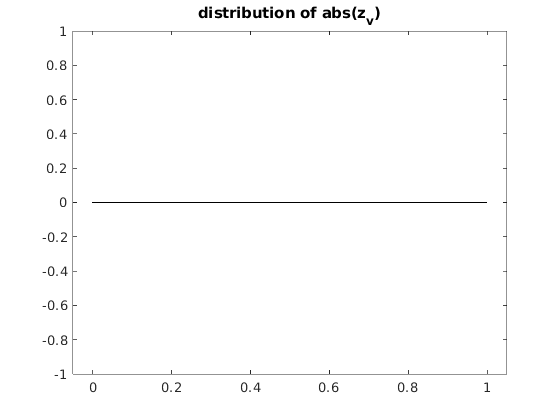

%useful for debugging when tolerances not satifactory
l = model.lb(model.SConsistentRxnBool);
u = model.ub(model.SConsistentRxnBool);
vi = vf - vr;
logvrvf = reallog(vr./vf);

figure
histogram(log10(abs(z_v)))
title('distribution of abs(z_v)')

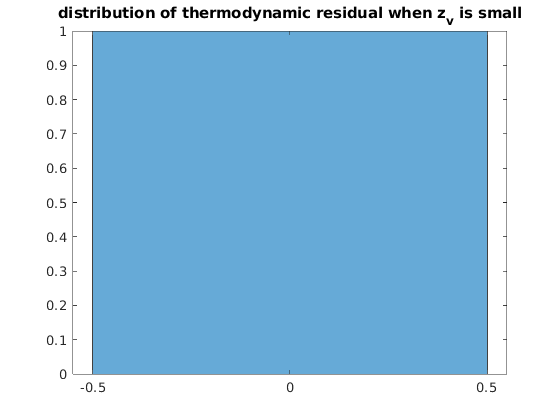


zBool = abs(z_v)>0.1;
if any(l(zBool)~=0)
    figure
    histogram(l(zBool))
    title('distribution of internal lower bound when z_v substantial')
end
if any(u(zBool)~=inf)
    figure
    histogram(u(zBool))
    title('distribution of internal upper bound when z_v substantial')
end

if any(zBool)
    figure
    histogram(res(zBool))
    title('distribution of thermodynamic residual when z_v is substantial')
end
if any(zBool)
    figure
    plot(vi(zBool),logvrvf(zBool),'.')
    xlabel('Small net flux')
    ylabel('Change in chemical potential')
end

if any(~zBool)
    %thermo residual is large even when z_v is small
    figure
    histogram(res(~zBool))
    title('distribution of thermodynamic residual when z_v is small')
end

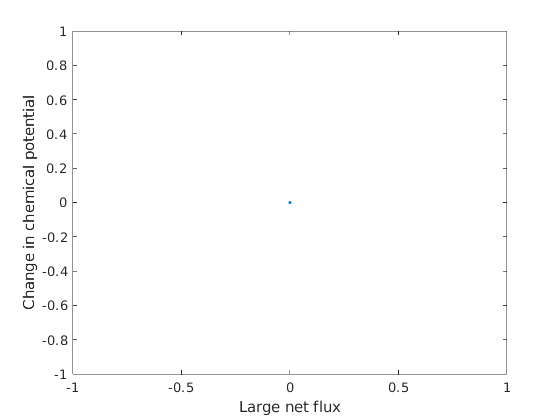

if any(~zBool)
    figure
    plot(vi(~zBool),logvrvf(~zBool),'.')
    xlabel('Large net flux')
    ylabel('Change in chemical potential')
end

rBool = abs(res)>0.001;
fwdBool = vi>0;
if any(rBool)
    ab = z_vf - z_vr;
    figure
    histogram(ab(rBool))
    title('distribution of z_vf - z_vr when residual is large')
end

if any(rBool)
    %deviation from thermodynamic constraint occuring when net flux is
    %substantial
    figure
    res1 = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N;
    histogram(res1(rBool))
    title('distribution of log(vr/vf) - 2*N''*y_N when residual is large')
end

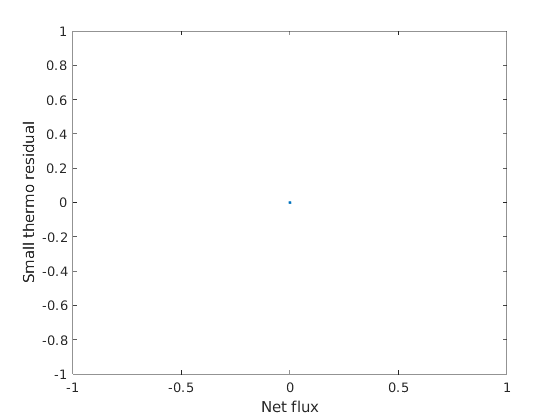

if any(rBool)
    figure
    plot(vi(rBool),res(rBool),'.')
    xlabel('Net flux')
    ylabel('Large thermo residual')
end
if any(rBool)
    figure
    plot(vi(rBool & fwdBool),res(rBool & fwdBool),'.')
    xlabel('Net flux')
    ylabel('Large thermo residual')
end
if any(rBool)
    figure
    if isfield(model,'C')
        res5 = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*C'*y_C - 2*z_v;
        histogram(res5(rBool))
        title('distribution of g.*log(vr/vf) + cr - cf - 2*ci - 2*N''*y_N - 2*C''*y_C - 2*z_v when residual is large')
    else
        res5 = g.*reallog(vr./vf) + cr - cf - 2*ci - 2*N'*y_N - 2*z_v;
        histogram(res5(rBool))
        title('distribution of g.*log(vr/vf) + cr - cf - 2*ci - 2*N''*y_N - 2*z_v when residual is large')
    end
end
if any(~rBool)
    figure
    plot(res(~rBool),vi(~rBool),'.')
    xlabel('Net flux')
    ylabel('Small thermo residual')
end

if any(rBool)
    figure
    plot(vi(~rBool & fwdBool),res(~rBool & fwdBool),'.')
    xlabel('Net flux')
    ylabel('Small thermo residual')
end

if isequal(modelToUse,'single')
    fprintf('%8.2g %s\n',norm(vf - exp(-(cf + cr - u0(1) - u0(2))/2)*x(1)), '|| vf - exp(-(cr + cf - u0 - u0)/2)*x1 ||')
end

   0.046 || vf - exp(-(cr + cf - u0 - u0)/2)*x1 ||
